clear all, close all, clc

############## ############### ############### ###############

## MARSSIM Statistics HW

## Prob-01

*If the containerized waste has an average surface dose rate which is calculated to be 1.73 mSv/hr with a standard deviation of 0.5 mSv/hr, what fraction of the containers will be expected to have a dose rate above the classification limit of 2 mSv/hr?*

Given,

mu = 1.73;          % mean; mSv/hr
sg = 0.5;           % std; mSv/hr
x = 2;              % classification limit; mSv/hr

Now, we know, $z=\frac{x-\mu \;}{\sigma }$

z = (x - mu)/sg

z = 0.5400

p = normcdf(z)      % area/ probablity at z

p = 0.7054

Also, this value can be verified from  cumilitive normal distribution table.

So, let's find the expected value-

p2 = 1 - p

p2 = 0.2946

(Ans)

############## ############### ############### ############### 

## Prob-02

*If the fissile content of the containers is required to be between 10 pCi/g and 200 pCi/g, what fraction of the container is expected to fall in this classification range if the average is expected to be 122 pCi/g with a standard deviation of 57 pCi/g?*

Given,

mu = 122;           % mean; pCi/g 
sg = 57;            % std
x1 = 10;            % min value
x2 = 200;           % max value

Now, the z scores be-

z1 = (x1 - mu)/sg   % upper bound

z1 = -1.9649

z2 = (x2 - mu)/sg   % lower bound

z2 = 1.3684

So, let's find the area value regarding these ze scores. Those could be found from the table provided

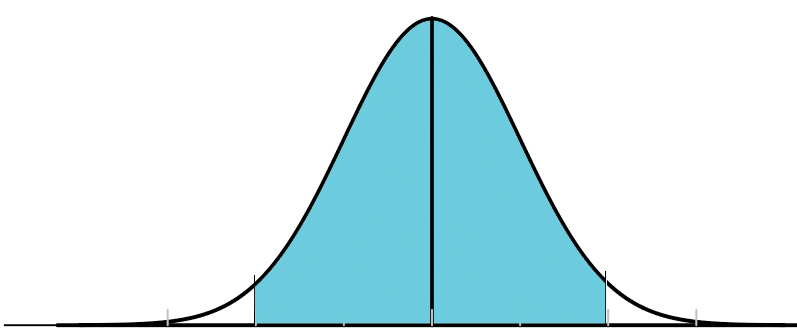

p1 = normcdf(z1)

p1 = 0.0247

p2 = normcdf(z2)

p2 = 0.9144

Then the area in between presents the desired fraction of containers

p = p2 - p1

p = 0.8897

(Ans)

############## ############### ############### ############### 

## Prob-03

*If 23 samples of the waste stream were characterized for specific heat values which demonstrated that the average value was 35.7 W/g with a standard deviation of 2.9 W/g, what is the probability that the population average is above the hypothetical transportation limit of 40 W/g?*

Given,

n = 23;             % no. of samples
mu = 35.7;          % mean; W/g
sg = 2.9;           % standard dev'; W/g
x = 40;             % hypothatical limit

so, $\textrm{SE}=\frac{\sigma }{\sqrt{\;n}}$

se = sg/sqrt(n)     % standard error

se = 0.6047


z = (x - mu)/sg

z = 1.4828

p = normcdf(z)      % probability at z

p = 0.9309

Then the probability that population average is above the hypothetical limit is-

p1 = 1 -p 

p1 = 0.0691

(Ans)

############## ############### ############### ############### 

## Prob-04

*If the waste stream is found to historically demonstrate liquid content of 0.87% by volume with a standard deviation of 0.12% for any given container volume, what is the probability that a container taken randomly will have a liquid content above the limit of 1%?*

Given,

mu = 0.87;          % mean; %
sg = 0.12;          % std
x = 1;              % desired limit; %

z = (x - mu)/sg

z = 1.0833

p = normcdf(z)      % probability at z

p = 0.8607

So, the probability of value to stay over that-

p1 = 1 -p 

p1 = 0.1393

(Ans)

############## ############### ############### ############### 

## Prob-05

*If 50 random aliquots of the waste stream show that the average pH of the material is 7.7 with a standard deviation 0.6, what is the probability that the true average of the waste will be above the limit of 8.2?*

Given,

n = 50;             % no. of samples
mu = 7.7;           % material ph; %
sg = 0.6;           % std
x = 8.2;            % desired limit; %

se = sg/sqrt(n)     % standard error

se = 0.0849


z = (x - mu)/sg 

z = 0.8333

p = normcdf(z)      % probability at z

p = 0.7977

So, the probability of value to stay over that

p1 = 1 -p 

p1 = 0.2023

(Ans)

############## ############### ############### ############### 

## Prob-06

*If the waste stream has historically shown that for every kg of product, an associated 0.21±0.03 kg of nuclear waste is generated requiring disposal. If the latest campaign generated 723 kg of product, what is the maximum amount of waste expected to be generated at the 95% confidence level?*

Given,

m = 723;            % nuclear product; kg
mu = 0.21*m         % average waste; kg

mu = 151.8300

sg = 0.03*m;        % std of waste

cl = 0.95;          % confidence level
z = norminv(cl)

z = 1.6449

As we know, $z=\frac{x-\mu \;}{\sigma }$

Then, the max' amount of waste at that confidence interval-

x = mu + z*sg       % ; kg

x = 187.5069

(Ans)

############## ############### ############### ############### 

## Prob-07

*General problem; describe the difference between a standard deviation and the standard error of the mean both mathematically and topically showing how they are related.*

**Standard Deviation: **it measures the spread of data-points from mean- within single sample.

$\sigma =\sqrt{\frac{\;\sum_{\;} \;{\left(x-\mu \right)}^2 }{n}\;}$    $\sigma =$ standard dev; $n=$ no. of sample/population; $\mu =$ mean

**Standard Error: **it measures variability of sample mean, across multiple samples- drawn from a population.


$$\textrm{SE}=\frac{\sigma \;}{\sqrt{\;n}}$$
    

Here, we see, the SE depends on $\sigma$. It decreses when n is larger, reflecting reduced uncertainty in the mean. 